# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder, any output images you might have saved and this livescript file.

Since we need to access the functions and data folder the first step is to add these two locations to MATLAB's path.

addpath('./functions');
addpath('./data');

# Lab 2: Learning and convolutional neural networks

## 2.1 Learning a Linear Classifier

In this part, we will try to learn a linear classifier for blood cell detection. Note that the classifier could also be viewed as a minimal neural network consisting of three parts: a scalar product node (or fully-connected node), a constant (or bias) term and a logistic sigmoid function. To find good parameters we will try to minimize the negative log-likelihood over a small training set.

The output from our classifier is a probability p for the input patch being centered at a cell centre. The sigmoid function will make sure that 0 ≤ p ≤ 1. To be more precise the output is


$$p=\frac{e^y }{1+e^y }\;\;\;\;\textrm{where}\;\;\;\;y=I\cdot \omega +\omega_0$$


Instead of testing a bunch of manually chosen w’s and w_0’s, we will try to learn good values for all the parameters. This requires training examples, that you find in cell_data.mat.

## Ex 2.1 

## Load the data using

load cell_data.mat

It loads a structure, cell_data, with two fields, `fg_patches` and `bg_patches`, corresponding to positive (centered blood cells) negative examples respectively.

## Ex 2.2 

Create two new variables, examples and labels. The variable examples should be a cell structure containing all the patches (both positives and negatives) and labels should be an array with the same number of elements such that `labels(i) = 1` if` examples{i}` is a positive example, and `labels(i) = 0` otherwise.

example=[cell_data.fg_patches,cell_data.bg_patches];
A=ones(1,size(cell_data.fg_patches,2));
B=zeros(1,size(cell_data.bg_patches,2));
Labels=[A,B];


## Ex 2.3

Split the data into training,` (examples_train, labels_train)`, and validation,` (examples_val, labels_val)`. The two should have a similar structure to examples and labels. Write on the report which percentage of the data you used for validation. Also, the splitting of the data into the two sets should be done in a random manner, for example, using randperm. 

**Percentage of data used for training**: 80%

**Percentage of data used for validation**: 20%

This dataset isn't too large, so we do'nt require the test set (devide in 3 parts). So we assume that 80-20 ratio is a good choice for this dataset.

train_percentage=0.8;
%calculating the length of our training patch
fg_train_length=ceil(size(cell_data.fg_patches,2)*train_percentage);

%Foreground cells
fg_train_patch=cell_data.fg_patches(1:fg_train_length);

fg_train_label=ones(1,fg_train_length);
fg_valid_patch=cell_data.fg_patches(fg_train_length+1:end);
fg_valid_label=ones(1,size(fg_valid_patch,2));

%Background cells
bg_train_length=ceil(size(cell_data.bg_patches,2)*train_percentage);

bg_train_patch=cell_data.bg_patches(1:bg_train_length);
bg_train_label=zeros(1,bg_train_length);
bg_valid_patch=cell_data.bg_patches(bg_train_length+1:end);
bg_valid_label=zeros(1,size(bg_valid_patch,2));

% train sets
examples_train=[fg_train_patch,bg_train_patch];
labels_train=[fg_train_label,bg_train_label];

% validation sets
examples_val=[fg_valid_patch,bg_valid_patch];
labels_val=[fg_valid_label,bg_valid_label];

## 2.2 Training the classifier

We will try to find parameters that minimize the negative log-likelihood on the training data. More precisely,


$$L\left(\theta \right)=\sum_{i\in S_+ } -\ln \left(p_i \right)+\sum_{i\in S_- } -\ln \left(1-p_i \right)=\sum_i L_i \left(\theta \right)$$


where $p_i$ refers to the classifier output for the ith training example. As in the lectures we will refer to the terms here as the partial loss $L_i$.

Before doing the next exercise, you need to work out how to compute the gradient of the partial loss $L_i$.

## Ex 2.4

Make a function

        `[wgrad, w0grad] = partial_gradient(w, w0, example_train, label_train)`

that computes the derivatives of the partial loss L_i with respect to each of the classifier parameters. Let the output wgrad be an array of the same size as the weight image, w (and let w0grad be a number). 

At each iteration of stochastic gradient descent, a training example, i, is chosen at random. For this example the gradient of the partial loss, L_i , is computed and the parameters are updated according to this gradient. The most common way to introduce the randomness is to make a random reordering of the data and then going through it in the new order. One pass through the data is called an epoch.

## Ex 2.5

Make a function

        `[w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train)`

that performs one epoch of stochastic gradient descent

## Ex 2.6 

Initialize `w = s * randn(35,35);`, with `s = 0.01` and `w0 = 0;` and run 5 epochs on your training examples. Plot w after each epoch (or after each iteration if you are curious), to get a sense of what is happening. Also, try using different `s={10,1,0.1,0.01}` and plot w after 5 epochs for each value of s. Include on the report visualizations of w for the different values of s, along with an written explanation of what is happening.

s is: 10


Final w:


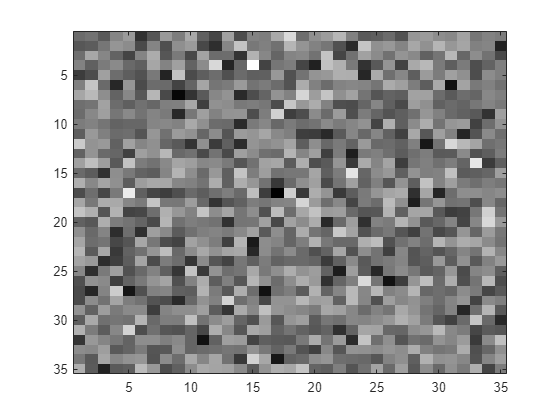

s is: 1


Final w:


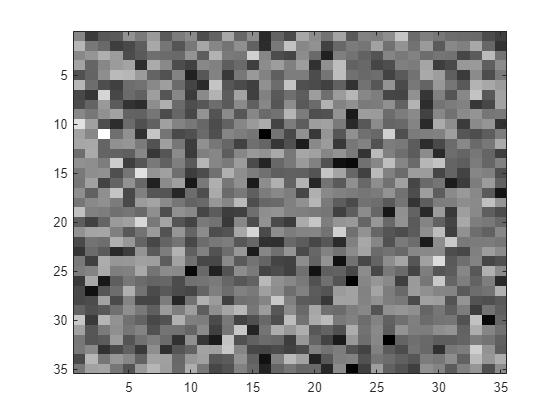

s is: 0.1


Final w:


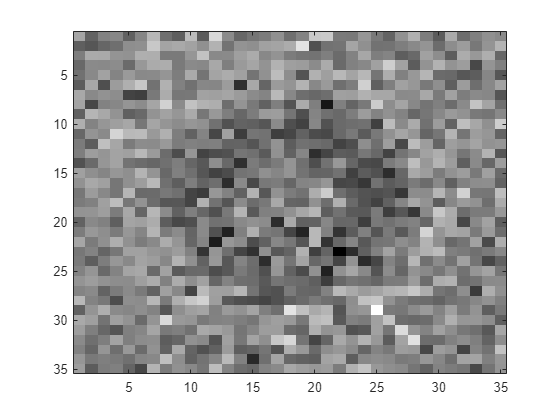

s is: 0.01


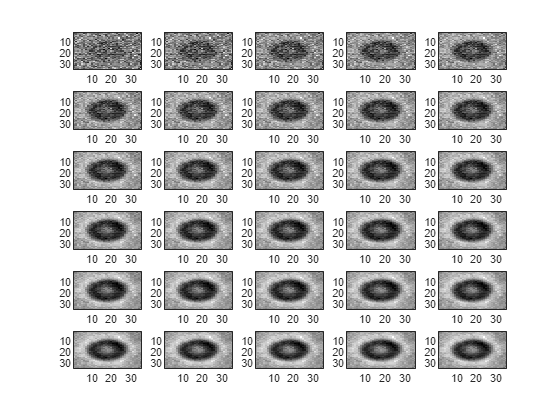

Final w:


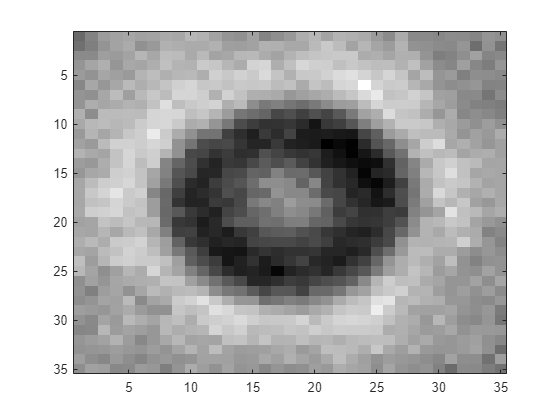

lrate = 0.001;
epochs = 30;
for s = [10, 1, 0.1, 0.01]
    w = s * randn(35, 35);
    w0 = 0;
    disp(['s is: ' num2str(s)])
    
    for n = 1:epochs
        [w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train);
        if s == 0.01
            figure(1)
            subplot(6,5,n), imagesc(w), colormap gray  
             
        end
    end
    disp(['Final w:']), figure, colormap gray, imagesc(w)
end

**Your written answer here:**

The value of s is limiting the pixel concentration behaving as a scaler for the whole w. While training, w gets updated according to its gradient. The output of the classifier effects the gradients of the w, which also effects the w itself. Since little early values of w will manage to create slight gradient values and then lead to a softer update of w.  Basically, gradients’ steps are little enough to get nearer to the local minimum, rather than getting far from it when the gradients are huge.

As can be seen in the above images for w, smaller values of s leads to smoother changes of w in comparison to large values of s.

## Exercise 2.7

As said before, at each iteration of stochastic gradient descent, a training example is chosen at random. Check what happens to w after 5 epochs when that training example is not chosen randomly but in sequence, i.e. first `i = 1`, then `i = 2`, and so on. Include on the report a visualization of w for this case. (Don’t forget to change back your function to a random choice of i after this exercise).

You can display the resulting filters inside this livescript notebook using the function imagesc.

Final w:


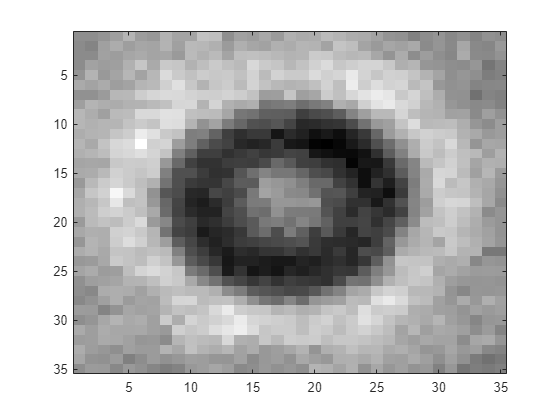

sequential = true;
lrate1=0.001;
s1 = 0.01;
w1 = s1 * randn(35, 35);
w01 = 0;
for n = 1:epochs
        [w1, w01] = process_epoch(w1, w01, lrate1, examples_train, labels_train);

end
    disp(['Final w:']), figure, colormap gray, imagesc(w1)

## Ex 2.8 

Make a function

        `predicted_labels = classify(examples_val,w,w0);`

that applies the classifier to the example data. After that, use it on `examples_train` and examples_val and check how much accuracy it gets for each by comparing the predicted labels with `labels_train` and `labels_val` respectively. Write on your report the highest accuracy you were able to achieve in the training and validation data. Hint: train the classifier for longer than 5 epochs to make sure that it converges.

When you have defined the function run the following code.

predicted_labels = classify(examples_val,w,w0);
correct = sum(predicted_labels==labels_val);
accuracy = 100*correct/length(labels_val);
fprintf(["Validation Accuracy: "]+accuracy+["%%"])

Validation Accuracy: 88.75%

**Write the highest accuracy you were able to get here:**

We acheived 88,75% acuuracy.

## Ex 2.9

The data for training this classifier consists on only 400 examples (less if you consider that you have split it into training and validation). To achieve higher accuracy it might be useful to perform some data augmentation before the training. In this exercise you will increase the number of elements in the training examples by M times. Make a function

        `[examples_train_aug,labels_train_aug] = augment_data(examples_train,labels_train,M)`

that takes each sample of the original training data and applies M random rotations (you can use Matlab function imrotate), from which result M new examples. Store these new examples in examples_train_aug and their corresponding labels in labels_train_aug. Train the classifier with this augmented data and write on your report the new values for accuracy on the training and validation examples.

M=5;
[examples_train_aug, labels_train_aug] = augment_data(examples_train, labels_train, M)

examples_train_aug = 1×1600 cell array
  Columns 1 through 555

    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}    {35×35 double}

labels_train_aug =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


lrate2 = 0.001;
epochs = 30;
s2 = 0.01;
w2 = s2 * randn(35, 35);
w02 = 0;
    for n = 1:epochs
        [w2, w02] = process_epoch(w2, w02, lrate2, examples_train_aug, labels_train_aug);
    end

predicted_labels = classify(examples_val,w2,w02);
correct = sum(predicted_labels==labels_val);
accuracy = 100*correct/length(labels_val);
fprintf(["Validation Accuracy: "]+accuracy+["%%"])

Validation Accuracy: 92.5%

**Write the highest accuracy you were able to get here:**

The highest accuracy was 92,5%.

## 2.3 Convolutional neural networks

In the last part, your task is to train convolutional neural networks using Matlab.

## `Ex 2.10 `

Run the following cell

[imgs, labels] = digitTrain4DArrayData;

to load a dataset of images of digits into Matlab. (Make sure you have the Deep Learning toolbox installed). You will find the 5000 digit images in imgs. Plot a few of them to see what the data looks like.

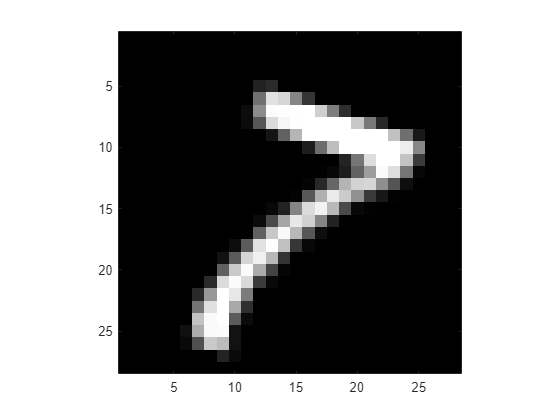

N = 3210; % We have 5000 images so any number between 1 and 5000 works.
img = imgs(:,:,:,N);
imagesc(img), axis image, colormap gray

The next step is to define a network for classification. In Matlab, you do this by simply giving an array of the layers. For example, this would be a linear classifier similar to the one you trained for cells:

        layers = [

            imageInputLayer([35 35 1]);

            fullyConnectedLayer(1);

            softmaxLayer();

            classificationLayer()];

## Ex 2.11 

Make a function

        `layers = basic_cnn_classifier()`

that implements the following network in Matlab:

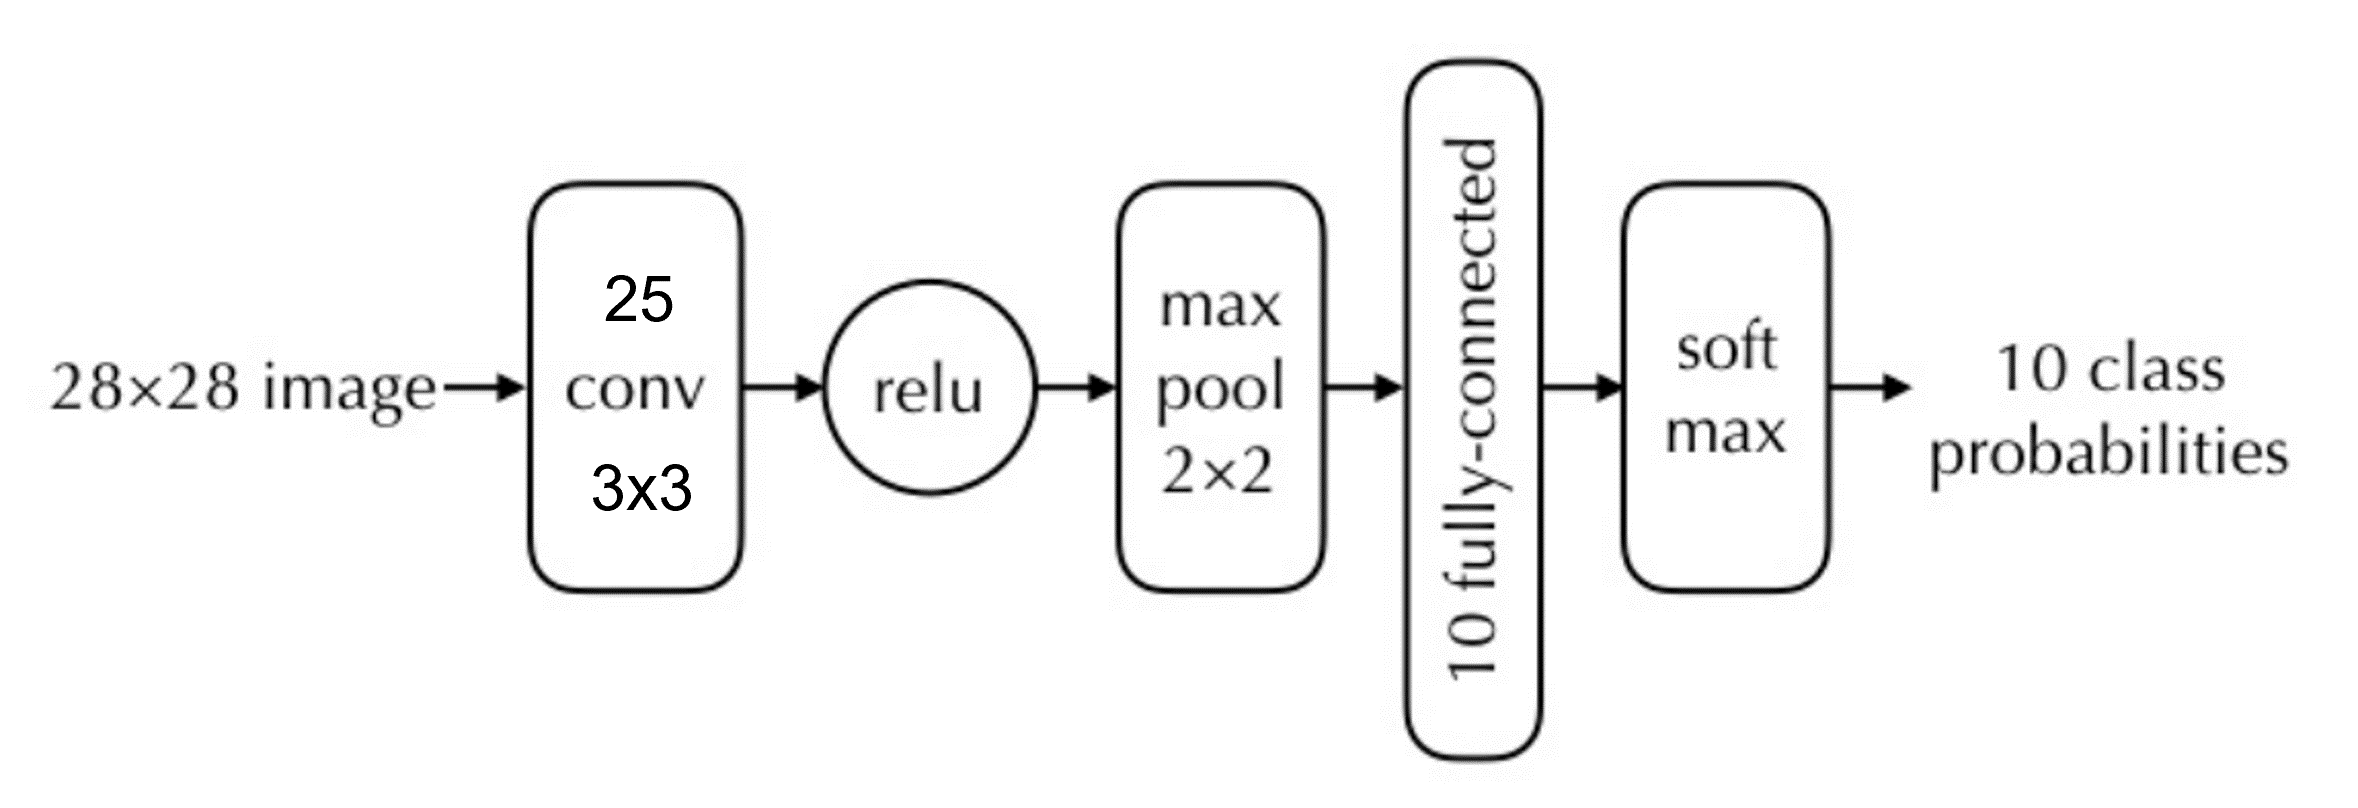

Apart from the layers above the functions `convolution2dLayer`, `reluLayer` and `maxPooling2dLayer` will be useful. Note that you have to set the *stride* for max pooling to 2 to get the expected downsampling.

When you have written the function run the following cell:

layers = basic_cnn_classifier()

layers =   7×1 Layer array with layers:

     1   ''   Image Input             28×28×1 images with 'zerocenter' normalization
     2   ''   Convolution             25 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Fully Connected         10 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

## Ex 2.12 

Create a set of training options telling Matlab to use stochastic gradient descent with momentum (SGDM), for the optimization:

        `options = trainingOptions('sgdm');`

Now train the network (using default parameters) by running

        net = trainNetwork(imgs, labels, layers, options)

options = trainingOptions('sgdm');
net = trainNetwork(imgs, labels, layers, options);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        9.38% |       2.3002 |          0.0100 |
|       2 |          50 |       00:00:00 |       59.38% |       1.6379 |          0.0100 |
|       3 |         100 |       00:00:01 |       65.62% |       1.1105 |          0.0100 |
|       4 |         150 |       00:00:01 |       53.91% |       1.2434 |          0.0100 |
|       6 |         200 |       00:00:02 |       67.19% |       0.9355 |          0.0100 |
|       7 |         250 |       00:00:03 |       75.00% |       0.8918 |          0.0100 |
|       8 |         300 |  

## Ex 2.13 

Try the network on a few of the training images. You can use `net.predict(img)` to get the ten output probabilities or `net.classify(img)` to get the most probable class.

N = 3210;
img = imgs(:,:,:,N);
net.predict(img)

ans = 1×10 single row vector
    0.0000    0.0000    0.0008    0.0001    0.0000    0.0000    0.0000    0.9990    0.0000    0.0001


net.classify(img)

ans = categorical
     7 


acc_count = nnz(net.classify(imgs) == labels); 
acc = acc_count / length(labels);
disp(['CNN accuracy: ' num2str(acc * 100) '%'])

CNN accuracy: 98.24%


## Ex 2.14 

Work out how many trainable parameters your network contains. Include the answer in your submission. If you explore what the data structure net actually contains, you can find the answer there as well. Note that the convolution layer does not use padding so the output from the convolution layer is smaller than the input.

**Write your answer here:**

The covolutional layer has (3*3*25=225) trainable parameters and for calculting the trainable parameters of the fully connected layer, we should calculate the size of the image at the input of the FC layer. The size of the image after the Conv filter would be (26*26), after passing through the max-pooling it decreases to (13*13), which is the ibput to FC layer. Thus, the number of trainable parameters of the FC layer is (13*13*10). The total number of trainable parameteres is: 225+1690=1915

## Ex 2.15 

Matlab prints a lot of output, for example the accuracy on the training set. Recall from the lectures that this number is not very good for judging the quality of a classifier. Instead we should save a subset of the data as a validation set, that we can use to evaluate the trained network. 

Divide the data into training `imgs` and `labels` into new variables `imgs_train, labels_train, imgs_val, labels_val`.

train_portion=0.8;
size_train=int32(size(imgs,4)*train_portion);

imgs_train=imgs(:,:,:,1:size_train);
labels_train=labels(1:size_train);

imgs_val=imgs(:,:,:,size_train+1:end);
labels_val=labels(size_train+1:end);

Make a function 

        `net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val) `

that runs a few epochs of training and then evaluates the accuracy on the validation set. In this case, Matlab has given us a separate test set, so we don’t have to save images for that purpose. *Matlab hints:* You can run multiple images at once by stacking them along the fourth dimension. If you want to continue training the same network you can run

        `net = train_classifier(net.Layers, imgs_train, labels_train, imgs_val, labels_val)`

net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val)

CNN Accuracy: 74%%


net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


 net = train_classifier(net.Layers, imgs_train, labels_train, imgs_val, labels_val)

CNN Accuracy: 91.7%%


net =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


**Ex 2.16 **

To run a convolutional neural network we have to perform a massive amount of computations. Hence it is very important to consider the computational load when designing a network. For the network below, compare (roughly) the time consumption of the blue and the red layers. You can ignore effects of padding. Include your answer and your motivation in your submission.

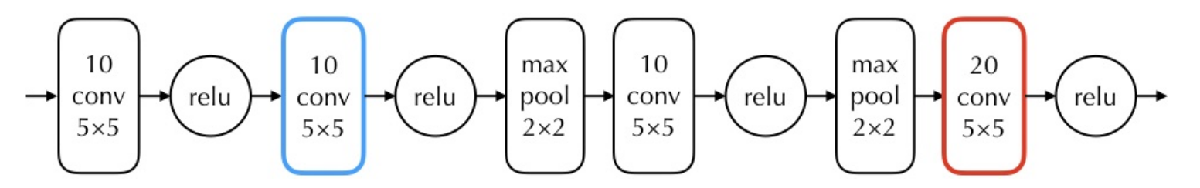

**Write your answer here:**

When considering the time consumption, we need to count just the number of multiplications. If we assume the size of the image as n*n, in the blue layer the number of multiplications would be (n*n*10*5*5*10). And for the red layer, the size of the image would decreased by passing through two max-pooling layers and results in a (n/4)*(n/4) image. Therefore, the number of multiplications in red layer is (n/4)*(n/4)*20*5*5*10. The number of multiplications in the blue layer is 8 times bigger than the red one, so it could be concluded that the time consumption in the blue layer is also 8 times longer than the red layer.

NOTE: You are not supposed to actually implement and train this network.

## Ex 2.17

Replace the blue box of the network in the figure above by a sequence of two layers of 10 3 × 3 convolutional filters. What changes in terms of network parameters, time consumption and accuracy? Again, you are not supposed to implement the network.

**Write your answer here:**

the number of parametres of the blue layer is: 10*5*5*10=2500

the number of parameters after replacing the blue layer with two layers: 10*3*3*10*2=1800

Thus, the number of parameters in the firts case is bigger than the second one, and similarlý the time consumption much higher in the first case.

for comparing the accuracy, we believe that applying two consecutive filters would usually results in improvement in accuracy. However, absense of relu and max-pooling layers might affect the accuracy negatively.  

## Ex. 2.18

Make a copy of basic_cnn_classifier.m and name it better_cnn_classifier.m. Try modifying the network by adding more layers. Also experiment with the training options. How much can you improve the results?

layers = better_cnn_classifier()

layers =   12×1 Layer array with layers:

     1   ''   Image Input             28×28×1 images with 'zerocenter' normalization
     2   ''   Convolution             25 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Convolution             30 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     6   ''   ReLU                    ReLU
     7   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''   Fully Connected         100 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         10 fully connected layer
    11   ''   Softmax                 softmax
    12   ''   Classification Output   crossentropyex

net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val);

CNN Accuracy: 98.5%%


## Ex 2.19 

Load the builtin test images using

        `[imgs_test, labels_test] = digitTest4DArrayData;`

Run the network on all the test images. You apply the network to an image using

        pred = net.classify(image)

Compute precision and recall for each of the 10 classes and include these in your submission. The definitions of precision and recall can be found in the lecture notes chapter 4.

 [imgs_test, labels_test] = digitTest4DArrayData;
 pred = net.classify(imgs_test);
 % based on the definition of the precision and recall, we found the
 % correct-classified and implemented the definitions in order to calculate
 % them
 for digit = 0:9
     index_correct_class=labels_test==num2str(digit);
     correct_classified=nnz(pred(index_correct_class)==num2str(digit));
     Precision=correct_classified/(nnz(pred==num2str(digit)));
     Recall=correct_classified/(length(labels_test( index_correct_class)));
     disp(['Precision for digit ' num2str(digit) ' : ' num2str(Precision)]);
    disp(['Recall for digit ' num2str(digit) '  : ' num2str(Recall)]);
    disp('%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%');
 end

Precision for digit 0 : 0.9939


Recall for digit 0  : 0.978


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Precision for digit 1 : 0.9841


Recall for digit 1  : 0.99


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Precision for digit 2 : 0.9919


Recall for digit 2  : 0.98


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Precision for digit 3 : 0.99383


Recall for digit 3  : 0.966


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Precision for digit 4 : 0.99798


Recall for digit 4  : 0.988


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Precision for digit 5 : 0.97839


Recall for digit 5  : 0.996


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Precision for digit 6 : 0.97255


Recall for digit 6  : 0.992


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Precision for digit 7 : 0.99398


Recall for digit 7  : 0.99


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Precision for digit 8 : 0.97461


Recall for digit 8  : 0.998


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Precision for digit 9 : 0.99401


Recall for digit 9  : 0.996


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Ex 2.20

Save three of the failure cases with names indicating what digit they were mistaken for. Include these in your submission. You can use imwrite(img, ’mistaken_as_5.png’) to save an image if it is correctly scaled. Have a look at the file before submitting it, so it looks right.

You can load and display the images here using imagesc:

Image mistaken as 6:


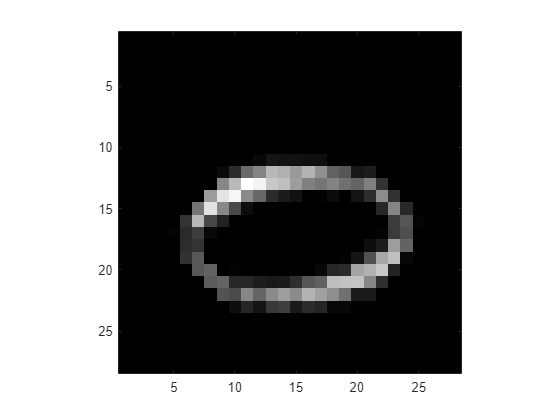

Image mistaken as 8:


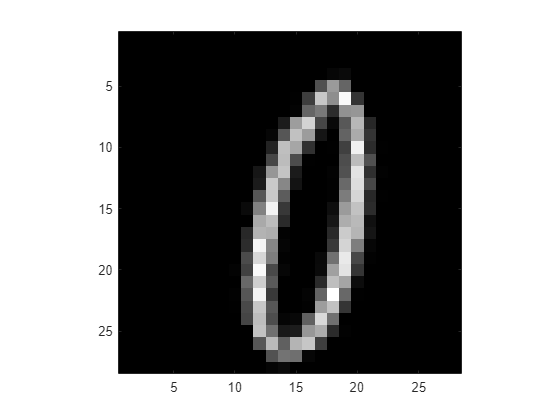

Image mistaken as 8:


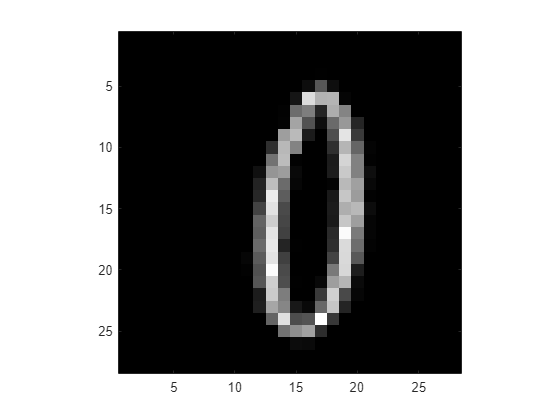

% finding the label of wrong-predicted image
 index_failure = pred ~= labels_test;
imgs_failure = imgs_test(:, :, :, index_failure);
labels_failure = pred(index_failure);

for n = 1:3
    disp(['Image mistaken as ' char(labels_failure(n)) ':'])
    figure, imagesc(imgs_failure(:, :, :, n)), axis image, colormap gray
    filename = strcat('./data/img', num2str(n), '_mistaken_as_', string(labels_failure(n)), '.png'); % Saving image
    imwrite(imgs_failure(:, :, :, n), filename);
end